## **AERO95002 Numerical Analysis 2019-2020**

## **Coursework 1**

## **Dr. Elnaz Naghibi**

## **Due Date: 17 February 2020**

### **Question 1 [15%]**

Plot the function $f\left(x\right)=\cos \;x\;\left(e^{2x} -2e^x +1\right)$ in the interval $\left\lbrack -\pi /4,3\pi /4\right\rbrack$ and find its roots using MATLAB functions.

Explore the four methods of root finding discussed in the lecture notes and select an efficient method to find each root. Discuss your rationale and provide the code presenting the most efficient method for each root. Show the convergence to each root using appropriate plots. Finally, compare the number of iterations required to obtain each root and discuss the reason behind the difference in convergence rates of the two roots.

**Answer:**

You can use this space to explain the answers and include equations as needed using either Latex code or the live script equation editor from the tab "insert".

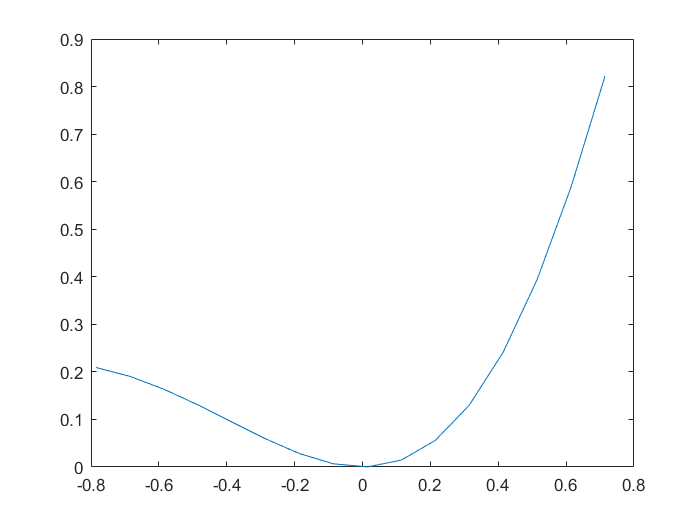

% Use this box for coding. 
% Outputs and graphs will be displayed on the right panel.
% To avoid submitting multiple files, please include functions at the bottom of your scripts.

clear
clc

x = -pi/4:0.1:pi/4;
y = fx(x);
%plot the diagram
plot(x,y);

%use newton method
x0 = 9;
while abs(fx(x0)) > 0.01
    x1 = x0 - fx(x0)/fbarX(x0);
    x0 = x1;
end
fprintf('The root of this function is %4.3f:',x0);

The root of this function is 7.854:

function y = fx(x)
 y = cos(x).*(exp(2.*x) - 2.*exp(x) + 1);
end

function dydx = fbarX(x)
 dydx = -sin(x) .*(exp(2.*x) - 2.*exp(x) + 1) + cos(x) .*(2.*exp(2.*x) - 2.*exp(x));  
end

### **Question 2 [30%]**

**Part a:  [15 %]**

Calculate Legendre polynomial of degree 5 using equation 16 in Handout_4 and MATLAB symbolic toolbox. Compare your resulting polynomial with "legendreP" function in MATLAB. Plot this function in the interval $\left\lbrack -1\ldotp 1\right\rbrack$ and calculate its roots $\eta_i$. Calculate weighting coefficients $w_i$ using the definition in equation 21. Using  $\eta_i$ and $w_i$, calculate the integral of  $\int_{-1}^2 \left({\textrm{ax}}^9 +{\textrm{bx}}^4 +\textrm{cx}\right)\;\textrm{dx}$ and show that it will be the same as its analytical value.

**Answer:**

**Part b: [15 %]**

Use mid-point, trapezium and Simpson integration schemes to calculate the below integrals for $n=25,50,100,200$ and provide the code for each method accordingly.


$$\int_0^{3\pi } \textrm{sinx}\;\textrm{dx}$$



$$\int_0^{3\pi } \left|\textrm{sinx}\right|\;\textrm{dx}$$



$$\int_0^{3\pi } \sin^2 x\;\textrm{dx}$$


Calculate the errors for every value of $n$ using analytical values of integration and list the order of accuracy of the schemes as you double $n$ in each round. Compare your calculated orders of accuracy with theoretical values in chapter 3.2 of the text book "‘Fundamentals of Engineering Numerical Analysis". Discuss how different choices of integrand functions can affect the order of accuracy in the numerical schemes. 

**Answer:**

### **Question 3 [25%]**

Use Chebyshev distribution to sample 5 values of function $f\left(x\right)=\frac{1}{\cosh \;x}$ in the interval $\left\lbrack -2,2\right\rbrack$. Write a code to calculate the cubic spline passing though these points. Increase the number of points to 15 and rebuild the cubic spline. Compare your results with equally-spaced arrays of function values for n=5 and n=15 and report the Euclidean norm of error in each case.

**Answer:**

### **Question 4 [30%]**

**Part a: [15 %]**

Using the MATLAB command "meshgrid", create a $100\;\times \;100$ grid on the interval $x,y$$\in \left\lbrack -1,1\right\rbrack$. Create the discretized values of the function $f\left(x,y\right)=x^3 +3{\textrm{yx}}^2$ in this interval. Calculate 2D distributions of $\frac{\partial f}{\partial x}$ and  $\frac{\partial f}{\partial y}$ using finite difference schemes (use central difference for interior points and forward/backward difference for the points on the boundary). Plot the numerically calculated profiles of  $\frac{\partial f}{\partial x}$ and  $\frac{\partial f}{\partial y}$ on planes$x=0$ and $y=0\ldotp 5$and compare them with the analytical profiles of the derivatives.

**Answer:**

**Part b: [15 %]**

Use the systematic method to construct the finite-difference approximation of  $\frac{{\mathrm{d}}^4 f}{\mathrm{d}x^4 }$ using the stencil $\left(-2,-1,0,1,2\right)$. Report the coefficients obtained and the order of the truncation error in this approximation. Comment under which circumstance this approximation will provide an exact solution.

**Answer:**